close all
clear all
l = 1; % Länge des Fadens in m

[t,u2] = ode45(@pendel_luftw, [0 100], [pi/4 0])

t =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0001
    0.0002
    0.0004


u2 =     0.7854         0
    0.7854   -0.0001
    0.7854   -0.0001
    0.7854   -0.0002
    0.7854   -0.0002
    0.7854   -0.0005
    0.7854   -0.0007
    0.7854   -0.0010
    0.7854   -0.0012
    0.7854   -0.0025


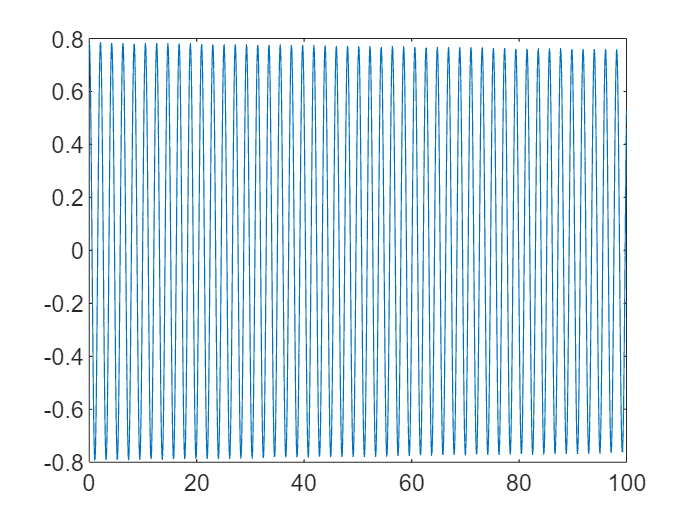

plot(t,u2(:,1))


u2(1,1)

ans = 0.7854

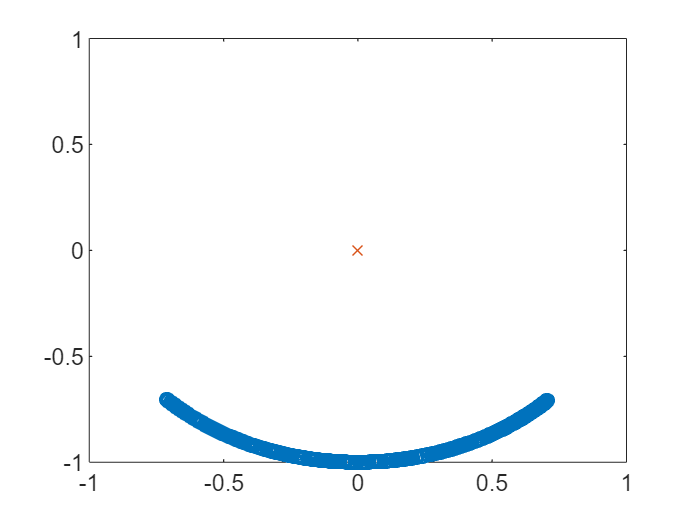


xkor = l * sin(u2(:,1));
ykor = -l * cos(u2(:,1));

plot(xkor, ykor, 'o')
hold on
plot(0,0,'x')
axis([-1 1 -1 1])
hold off